# Bias-Variance Trade-off 

You've just seen that while simple models (large bias, small variance) are usually easier to interpret, faster to train, and computationally less demanding to use, they may not capture the trends and patterns in your data as well as possible. However, you also saw that as model complexity increases (smaller bias, larger variance), eventually you get to a point where you "overfit" the data you use to train. That is, your model will capture capricious, unreproducible variations (noise) in the training data. Therefore, it will not generalize well to any other data, e.g. a set of test data you've set aside. This is the *bias-variance trade-off! *

In the script below, you can explore this trade-off. 

## Small Example

To understand the trade-off a bit better, start with a simple, small example with 20 points of data: essentially noise corrupted samples from a parabola (which of course, you would not know in practice). 

Use the button below to re-generate random data (i.e. random noise) for this example. 

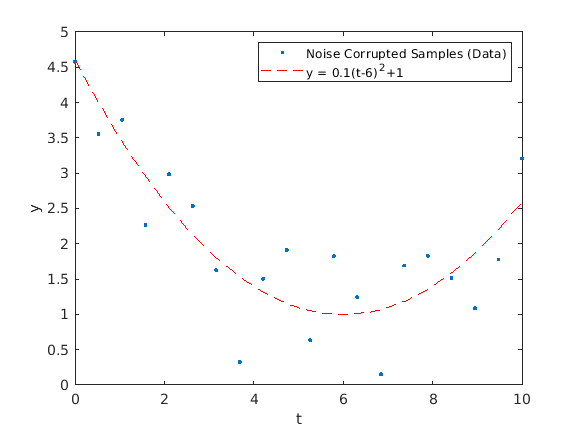

 
% To be used for plotting smooth versions of the functions 
t = linspace(0,10,100)'; 

% Choose the number of data points. 
nData1 = 20; 
k1 = linspace(0,10,nData1)'; % points to generate data and noise

% Generate the "perfect" function (unknown to us) 
x0 = 0.1*(t-6).^2+1; 

% Generate the "perfect" data (unknown to us) 
x1 = 0.1*(k1-6).^2+1; 

n1 = 0.5*randn(size(x1)); % generate the noise / corruption for the "known / observed" data
y1 = x1 + n1; % generate the observed data 

clf; 
plot(k1,y1,'.',t,x0,'r--')
xlabel("t");
ylabel("y");
legend("Noise Corrupted Samples (Data)","y = 0.1(t-6)^2+1")

Next, split the data in half into a training and test set, and fit three linear (polynomial) models to the training data:

- A 1st order, "straight line" model 

- A 2nd order, "quadratic"  model 

- A 9th order, "higher order polynomial" model

The training data, test data, and model polynomial are shown in the following figure. 

*Use the live control below to choose which model is shown.* 

% separate out train/test data 
% use cvpartiation for consistency of workflow 
part1 = cvpartition(length(y1),'holdout',0.5);
ytest1 = y1(test(part1));
ktest1 = k1(test(part1));
ytrain1 = y1(training(part1));
ktrain1 = k1(training(part1));

% train a few models, one underfitting, one fitting, one overfitting
% tic
linearModel1 = fitlm(ktrain1,ytrain1);
trainMetrics1 = rMetrics(ytrain1,linearModel1.Fitted);
testMetrics1 = rMetrics(ytest1,linearModel1.predict(ktest1));

linearModel2 = fitlm(ktrain1 ,ytrain1,'poly2'); 
trainMetrics2 = rMetrics(ytrain1,linearModel2.Fitted);
testMetrics2 = rMetrics(ytest1,linearModel2.predict(ktest1));

linearModel9 = fitlm(ktrain1,ytrain1,'poly9'); 
trainMetrics9 = rMetrics(ytrain1,linearModel9.Fitted);
testMetrics9 = rMetrics(ytest1,linearModel9.predict(ktest1));

chosenModel = linearModel9; 

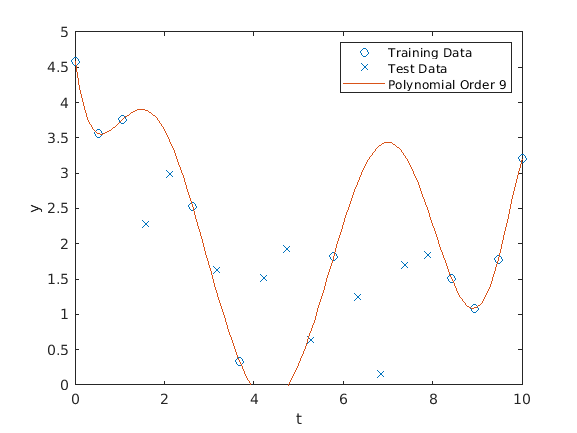

chosenModelOrder = height(chosenModel.Coefficients)-1; 
clf; 
% plot(ktrain1,ytrain1,'bo',ktest1,ytest1,'bx',t1,chosenModel.predict(t1))
colors = lines(2); 
plot(ktrain1,ytrain1,"Color",lines(1),"Marker","o","Linestyle","none"); hold on; 
plot(ktest1,ytest1,"Color",lines(1),"Marker","x","Linestyle","none"); 
plot(t,chosenModel.predict(t),"Color",colors(2,:)); hold off; 

axis([0,10,0,5])

legend("Training Data","Test Data","Polynomial Order "+string(chosenModelOrder))
xlabel("t"); 
ylabel("y"); 


% get(gcf,"Position")
% set(gcf,"Position",[0 0 800 500]) 

The quantitative metrics for how well the model fits both the training and test data are given below. 

Training_Metrics = rMetrics(ytrain1,chosenModel.Fitted)

Training_Metrics = 1×4 table
       mae           mse           rmse       Rsq
    __________    __________    __________    ___

    1.8034e-13    6.1641e-26    2.4828e-13     1 


Test_Metrics = rMetrics(ytest1,chosenModel.predict(ktest1))

Test_Metrics = 1×4 table
     mae       mse       rmse       Rsq  
    ______    ______    ______    _______

    1.3213    2.5666    1.6021    -3.5067


Notice that the model seems to fit the training data closer as you increase the polynomial order (model variance). In fact, since there are only 10 points in the training data, the 9th order polynomial model will fit the training data with essentially no error. (This is always true for polynomial models, but don't worry about the mathematical reason.) However, it does not do so well when it comes to the test data. A comparison of all three models is shown below. 

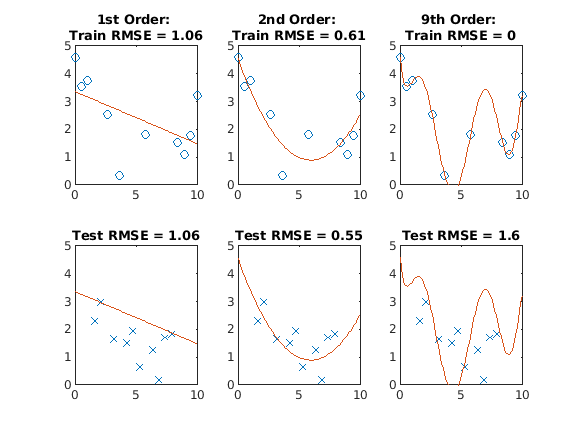

decPlaces = 2; 

clf; 
tiledlayout(2,3); 
nexttile; 
plot(ktrain1,ytrain1,'o'); 
hold on; 
plot(t,linearModel1.predict(t))
hold off; 
axis([0,10,0,5])
title(["1st Order: " ;  "Train RMSE = " + string(round(trainMetrics1.rmse,decPlaces)) ])

nexttile; 
plot(ktrain1,ytrain1,'o'); 
hold on; 
plot(t,linearModel2.predict(t))
hold off; 
axis([0,10,0,5])
title(["2nd Order: " ;  "Train RMSE = " + string(round(trainMetrics2.rmse,decPlaces)) ])

nexttile; 
plot(ktrain1,ytrain1,'o'); 
hold on; 
plot(t,linearModel9.predict(t))
hold off; 
axis([0,10,0,5])
title(["9th Order: " ;  "Train RMSE = " + string(round(trainMetrics9.rmse,decPlaces)) ])


nexttile; 
plot(ktest1,ytest1,'x'); 
hold on; 
plot(t,linearModel1.predict(t))
hold off; 
axis([0,10,0,5])
title("Test RMSE = " + string(round(testMetrics1.rmse,decPlaces)) )

nexttile; 
plot(ktest1,ytest1,'x'); 
hold on; 
plot(t,linearModel2.predict(t))
hold off; 
axis([0,10,0,5])
title("Test RMSE = " + string(round(testMetrics2.rmse,decPlaces)) )

nexttile; 
plot(ktest1,ytest1,'x'); 
hold on; 
plot(t,linearModel9.predict(t))
hold off; 
axis([0,10,0,5])
title("Test RMSE = " + string(round(testMetrics9.rmse,decPlaces)) )

You can see that--with the exception of rare, anomalous instances--the 1st order (straight line) model does not fit either the training or the test data as well as the 2nd order (quadratic) model. Moreover the 9th order polynomial model, while fitting the training data essentially perfectly, does a far worse job of fitting the test data. Of course, you know in this case that the "best fit" polynomial model *should* be 2nd order since that was the original function the data was generated from with added noise. However, using the bias-variance trade-off concept, you can determine this in practice when you do not have a known--or there is no--underlying function. 

## Larger Example

The concepts exhibited by the example above are of course not limited to cases of small data. To show this, you'll see an example with 10,000, noise corrupted data points (instead of 20) for the same underlying parabola. Use the button below to re-generate random data for this example. 

 
nData = 1e4; 
k = linspace(0,10,nData)'; % points to generate data and noise

% Generate the "perfect" data (unknown to us) 
x = 0.1*(k-6).^2+1; 

Use the slider below to adjust the amount of "noise" added to the data. (Note, you can add zero noise to the data in which case every model will fit more or less the same.)

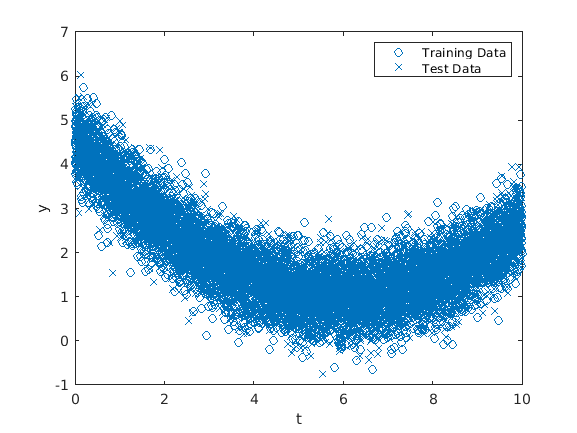

noiseMultiplier = 1 ;
n = noiseMultiplier*0.5*randn(size(x)); % generate the noise / corruption for the "known / observed" data
y = x + n; % generate the observed data 

% 
% clf; 
% plot(k,y,'.'); 
% xlabel("k"); 
% ylabel("y"); 
% title("Response Data")


% separate out train/test data 
% use cvpartiation for consistency of workflow 
part = cvpartition(length(y),'holdout',0.4);
ytest = y(test(part));
ktest = k(test(part));

ytrain = y(training(part));
ktrain = k(training(part));

clf; 
colors = lines(1); 
plot(ktrain,ytrain,"color",colors(1,:),"Marker","o","Linestyle","none"); hold on; 
plot(ktest,ytest,"color",colors(1,:),"Marker","x","Linestyle","none"); hold off; 

legend("Training Data","Test Data");
xlabel("t"); 
ylabel("y"); 


% tic
minLeafSizes = round(logspace(log10(2000),0,10));
% minLeafSizes = round(linspace(3000,1,10))
models = cell(size(minLeafSizes)); 

trainMetrics = cell(size(minLeafSizes)); 
trainErrors = double(size(minLeafSizes));

testMetrics = cell(size(minLeafSizes)); 
testErrors = double(size(minLeafSizes));

for idx = 1:length(minLeafSizes)
   models{idx} = fitrtree(ktrain,ytrain,"minleafsize",minLeafSizes(idx));
   trainMetrics{idx} = rMetrics(ytrain,models{idx}.predict(ktrain));
   testMetrics{idx} = rMetrics(ytest,models{idx}.predict(ktest)); 
   trainErrors(idx) = trainMetrics{idx}.rmse; 
   testErrors(idx) = testMetrics{idx}.rmse;
end
% toc



This time, we'll fit several tree models to the training data with progressively smaller minimum leaf size (i.e. progressively increasing variance). The resulting RMSE for both the training and test data is shown below as a function of increasing variance below. 

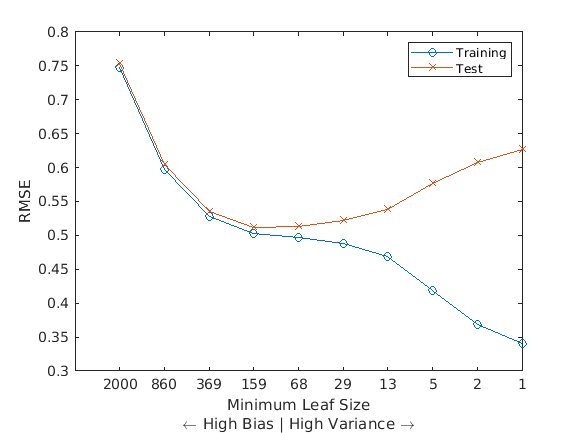

clf; 
plot(trainErrors,'o-'); hold on; 
plot(testErrors,'x-'); hold off; 
ax = gca; 
xticks(1:length(minLeafSizes)); 
xticklabels(minLeafSizes); 
% ax.XTickLabelRotation = 45; 
xlabel(["Minimum Leaf Size" ;  "\leftarrow High Bias | High Variance \rightarrow"])
ylabel("RMSE")
legend(["Training" , "Test"])


% %Alternative using the built-in logarithmic axis plotting 
% clf; 
% semilogx(minLeafSizes,trainErrors,'o-'); hold on; 
% semilogx(minLeafSizes,testErrors,'x-'); hold off; 
% set(gca,"XDir","reverse");  
% xlim([minLeafSizes(end) minLeafSizes(1)]);
% xlabel(["Minimum Leaf Size" ;  "\leftarrow High Bias | High Variance \rightarrow"])
% ylabel("RMSE")
% legend(["Training" , "Test"])






Here, you see an animation of the example with unity "Noise Multiplier" over the various models. Note that training error continues to decrease while at some variance, testing error begins to climb. 

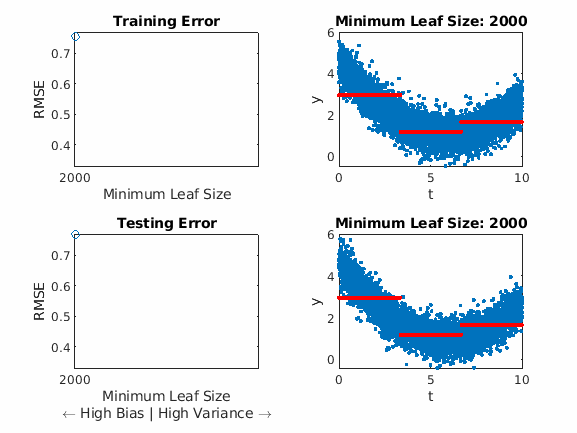

To look at the specific performance of a model trained above use the slider below:

modNum = 5; 
disp("Minimum Leaf Size: "+ string(minLeafSizes(modNum)))

Minimum Leaf Size: 68


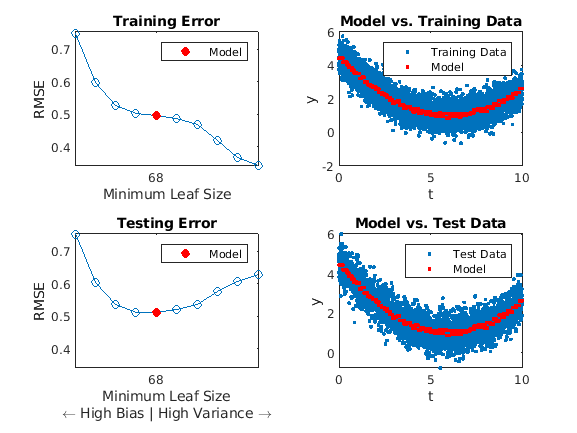


clf; 
tiledlayout(2,2); 
nexttile(2); 
plot(ktrain,ytrain,'.'); hold on; 
p1 = plot(ktrain,models{modNum}.predict(ktrain),"r."); hold off;
% t1 = title("Minimum Leaf Size: "+string(models{modNum}.ModelParameters.MinLeaf));
title("Model vs. Training Data")
ylabel("y")
xlabel("t")
legend(["Training Data", "Model"])
nexttile(1); 
plot(trainErrors,'o-'); hold on; 
p2 = plot(modNum,trainErrors(modNum),'or',"MarkerFaceColor",p1.Color); hold off; 
legend(p2,"Model")
xlim([1 length(minLeafSizes)]);
ylim([min([trainErrors,testErrors]) max([trainErrors,testErrors])]);
xticks(modNum); 
xticklabels(minLeafSizes(xticks));
ylabel("RMSE")
xlabel("Minimum Leaf Size")
t2 = title("Training Error");
nexttile(4); 
plot(ktest,ytest,'.'); hold on; 
p3 = plot(ktest,models{modNum}.predict(ktest),"red.","LineWidth",2); hold off;
% t3 = title("Minimum Leaf Size: "+string(models{modNum}.ModelParameters.MinLeaf));
title("Model vs. Test Data")
ylabel("y")
xlabel("t")
legend(["Test Data", "Model"])
nexttile(3); 
plot(testErrors,'o-'); hold on; 
p4 = plot(modNum,testErrors(modNum),'or',"MarkerFaceColor",p3.Color); hold off; 
legend(p4,"Model")
xlim([1 length(minLeafSizes)]);
ylim([min([trainErrors,testErrors]) max([trainErrors,testErrors])]);
xticks(modNum); 
xticklabels(minLeafSizes(xticks));
ylabel("RMSE")
xlabel(["Minimum Leaf Size" ;  "\leftarrow High Bias | High Variance \rightarrow"])
t4 = title("Testing Error");

% % Animation of Training and Test Error 
% 
% clf; 
% tiledlayout(2,2); 
% nexttile(2); 
% plot(ktrain,ytrain,'.'); hold on; 
% p1 = plot(ktrain,models{1}.predict(ktrain),"red."); hold off;
% t1 = title("Minimum Leaf Size: "+string(models{1}.ModelParameters.MinLeaf));
% xlabel("t"); 
% ylabel("y");
% nexttile(1); 
% p2 = semilogx(minLeafSizes(1),trainErrors(1),'o-');
% ax2 = gca; 
% % set(ax2,"XDir","reverse"); 
% ax2.XLim = [1 length(minLeafSizes)];
% % ax2.XLim = [minLeafSizes(end) minLeafSizes(1)];
% ax2.YLim = [min([trainErrors,testErrors]) max([trainErrors,testErrors])];
% ax2.XTick = 1;
% ax2.XTickLabels = minLeafSizes(ax2.XTick);
% ylabel("RMSE")
% xlabel("Minimum Leaf Size")
% t2 = title("Training Error");
% nexttile(4); 
% plot(ktest,ytest,'.'); hold on; 
% p3 = plot(ktest,models{1}.predict(ktest),"red.","LineWidth",2); hold off;
% t3 = title("Minimum Leaf Size: "+string(models{1}.ModelParameters.MinLeaf));
% xlabel("t"); 
% ylabel("y");
% nexttile(3); 
% p4 = semilogx(minLeafSizes(1),testErrors(1),'o-');
% ax4 = gca; 
% % set(ax4,"XDir","reverse"); 
% % ax4.XLim = [minLeafSizes(end) minLeafSizes(1)];
% ax4.XLim = [1 length(minLeafSizes)];
% ax4.YLim = [min([trainErrors,testErrors]) max([trainErrors,testErrors])];
% % ax.XTickLabel = minLeafSizes;
% ax4.XTick = 1;
% ax4.XTickLabels = minLeafSizes(ax4.XTick);
% ylabel("RMSE")
% xlabel(["Minimum Leaf Size" ;  "\leftarrow High Bias | High Variance \rightarrow"])
% t4 = title("Testing Error");
% % set(gcf,"Position",[1000 918 1000 350]) 
% 
% pause(1)
% for modNum=1:10
%    p1.YData = models{modNum}.predict(ktrain);
%    t1.String =  "Minimum Leaf Size: "+string(models{modNum}.ModelParameters.MinLeaf);
%    p2.XData = 1:modNum; 
%    p2.YData = trainErrors(1:modNum); 
%    ax2.XTick = modNum;
%    ax2.XTickLabels = minLeafSizes(ax2.XTick); 
%    p3.YData = models{modNum}.predict(ktest);
%    t3.String =  "Minimum Leaf Size: "+string(models{modNum}.ModelParameters.MinLeaf); 
%    p4.YData = testErrors(1:modNum); 
% %    p4.XData = minLeafSizes(1:modNum); 
%    p4.XData = 1:modNum; 
%    ax4.XTick = modNum;
%    ax4.XTickLabels = minLeafSizes(ax4.XTick);
%    pause(1)
%    drawnow
%    
% %     % Uncomment the code below to save the animation to a GIF file
% %       filename = 'testAnimated.gif';
% %       % Capture the plot as an image    
% %       frame = getframe(gcf); 
% %       im = frame2im(frame); 
% %       [imind,cm] = rgb2ind(im,256); 
% %       % Write to the GIF File 
% %       if modNum == 1 
% %           imwrite(imind,cm,filename,'gif', 'Loopcount',inf,'DelayTime',1); 
% %       else 
% %           imwrite(imind,cm,filename,'gif','WriteMode','append','DelayTime',1); 
% %       end 
% end
